s = tf('s');
P = 8 / ((s-4.427)*(s+4.427));
[M, N, X, Y] = coprime(P, 10);
zpk(M)

ans =
 
  (s+4.427) (s-4.427)
  -------------------
     (s+20) (s+10)
 
Continuous-time zero/pole/gain model.



zpk(N)

ans =
 
        8
  -------------
  (s+20) (s+10)
 
Continuous-time zero/pole/gain model.



zpk(X)

ans =
 
  1647 (s+4.999)
  --------------
  (s+10) (s+20)
 
Continuous-time zero/pole/gain model.



zpk(Y)

ans =
 
  (s^2 + 60s + 1320)
  ------------------
    (s+10) (s+20)
 
Continuous-time zero/pole/gain model.



zpk(N*X)

ans =
 
   13176 (s+4.999)
  -----------------
  (s+20)^2 (s+10)^2
 
Continuous-time zero/pole/gain model.



zpk(M*Y)

ans =
 
  (s+4.427) (s-4.427) (s^2 + 60s + 1320)
  --------------------------------------
            (s+20)^2 (s+10)^2
 
Continuous-time zero/pole/gain model.



minreal(N * X + M * Y)

8 states removed.

ans =
 
  D = 
       u1
   y1   1
 
Static gain.



evalfr(minreal(Y), 0)

ans = 6.5980

evalfr(minreal(N), 0)

ans = 0.0400


Q = evalfr(Y, 0) / evalfr(N, 0)

Q = 164.9498

C = (X + M * Q) / (Y - N * Q);
C = minreal(C);

7 states removed.


zpk(C)

ans =
 
  164.95 (s^2 + 9.985s + 30.31)
  -----------------------------
            s (s+60)
 
Continuous-time zero/pole/gain model.



sys = P * C / (1 + P * C);
sys = minreal(sys);

5 states removed.


zpk(sys)

ans =
 
  1319.6 (s^2 + 9.985s + 30.31)
  -----------------------------
        (s+20)^2 (s+10)^2
 
Continuous-time zero/pole/gain model.



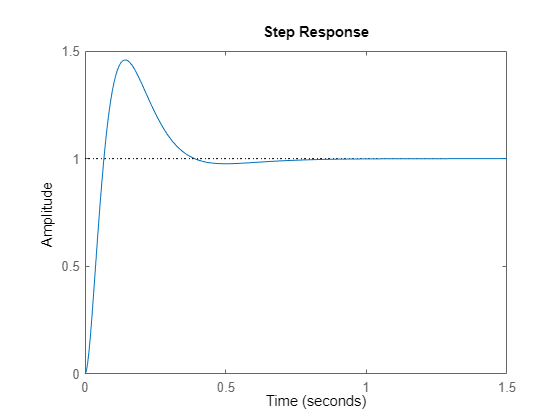

step(sys, 1.5)

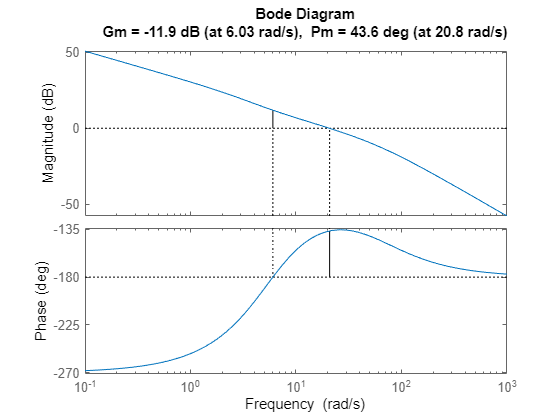

margin(P*C)
hold off

P4

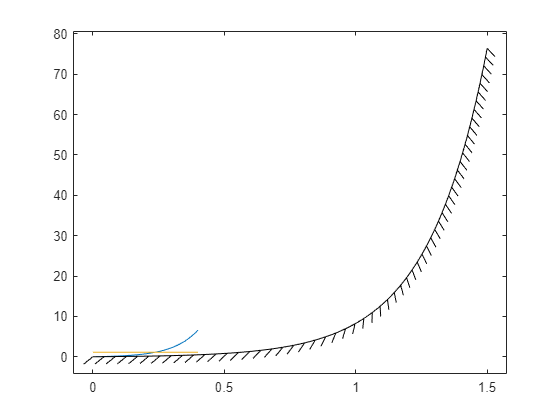

tr = 0:0.01:1.5;
Y_os = 0.1 * (exp(4.427 * tr) - 1);
boundaryline(tr, Y_os)

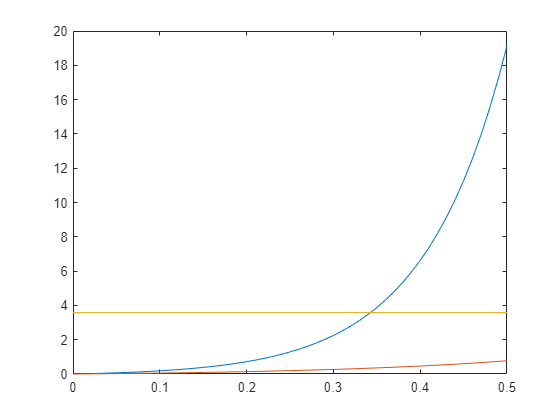

tr = 0:0.01:0.5;
y_os_2 = 0.1 * (exp(10.52 * tr) - 1);
plot(tr, y_os_2)
hold on;
y_3 = 0.1 * (exp(4.331 * tr) - 1);
plot(tr, y_3)
%yline(5.539 / (10.52 - 5.539))
cons = (4.331 / (5.539-4.331)) + zeros( 1, max(size(tr)) );
plot(tr, cons)
hold off

tr = 0:0.01:0.5;
y_os_2 = 0.1 * (exp(10.52 * tr) - 1);
